syms x
%Normal function
f = @(x) (x^2*log(x))

f = function_handle with value:
    @(x)(x^2*log(x))


%Derivative function
Der01 = diff(f(x))

$$Der01 = x+2\,x\,\log\left(x\right)$$

Der01_value = vpa(subs(Der01,2),15)

$$Der01\_value = 4.77258872223978$$

Con h = 0.01

x0 = 2;
h = 0.01;
Der1_Adelante = (f(x0+h) - f(x0))/h

Der1_Adelante =    4.794536839920172


x0 = 2;
h = 0.01;
Der1_Atras = (f(x0)-f(x0-h))/h

Der1_Atras =    4.750673937975947


x0 = 2;
h = 0.01;
Der1_Central = (f(x0+h) - f(x0-h))/(2*h)

Der1_Central =    4.772605388948059


Cálculo de errores con las derivadas

Ea_Adelante = abs(Der1_Adelante - Der01_value)

$$Ea\_Adelante = 0.021948117680390307135445235764849$$

Er_Adelante = Ea_Adelante/Der01_value

$$Er\_Adelante = 0.0045987867293308338756349475184044$$

Ea_Atras = abs(Der1_Atras - Der01_value)

$$Ea\_Atras = 0.021914784263834623026463324201984$$

Er_Atras = Ea_Atras/Der01_value

$$Er\_Atras = 0.0045918023821566569439960896540247$$

Ea_Central = abs(Der1_Central - Der01_value)

$$Ea\_Central = 0.000016666708277842054490955781432399$$

Er_Central = Ea_Central/Der01_value

$$Er\_Central = 0.0000034921735870884658194289321898593$$

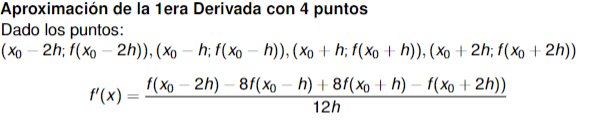

format long
x0=2;
h=0.01;
Der1_4p=(f(x0-2*h)-8*f(x0-h)+8*f(x0+h)-f(x0+2*h))/(12*h)

Der1_4p =    4.772588722073035


errorABS=abs(Der1_4p-Der01_value)

$$errorABS = 0.00000000016674626518715196754573046322712$$

errorREL = errorABS/Der01_value

$$errorREL = 0.000000000034938326952442228954961816455008$$

syms x y 
f = @(x,y) (exp(x)*sin(y))

f = function_handle with value:
    @(x,y)(exp(x)*sin(y))


diffx = diff(f, x)

$$diffx = {\mathrm{e}}^{x}\,\sin\left(y\right)$$

diffy = diff(f, y)

$$diffy = {\mathrm{e}}^{x}\,\cos\left(y\right)$$


ExactoX = vpa(subs(diffx, [x y], [2 3]),15)

$$ExactoX = 1.0427436562359$$

ExactoY = vpa(subs(diffy, [x y], [2 3]),15)

$$ExactoY = -7.3151100949011$$


h = 0.01;
AdelX = vpa(subs(diffx, [x y], [2+h 3]),15)

$$AdelX = 1.05322340420703$$

AtraX = vpa(subs(diffx, [x y], [2-h 3]),15)

$$AtraX = 1.03236818349936$$

AproxX = (AdelX-AtraX) / (2*h)

$$AproxX = 1.0427610353837371907563966259283$$

ErrorRELX = abs(ExactoX - AproxX)/abs(ExactoX)

$$ErrorRELX = 0.000016666750000198414048970763632857$$


AdelY = vpa(subs(diffy, [x y], [2+h 3]),15)

$$AdelY = -7.38862817359394$$

AtraY = vpa(subs(diffy, [x y], [2-h 3]),15)

$$AtraY = -7.2423235333137$$

AproxY = (AdelY-AtraY) / (2*h)

$$AproxY = -7.3152320140122781618568738375109$$

ErrorRELY = abs(ExactoY - AproxY)/abs(ExactoY)

$$ErrorRELY = 0.000016666750000198413952427390339925$$